## **Why Euler/Cardan angles fail to represent joint rotations correctly**

In this appendix, the orientation of the humerus with respect to the torso will be denoted by a sequence of 3 numbers indicating the plane of elevation (PoE), elevation, and axial rotation as indicated by the International Society of Biomechanics (ISB) [1]. For example, if at rest the arm is at 20° PoE, -20° of elevation (negative numbers indicate higher elevation per ISB standards), and -10° of axial rotation (negative numbers indicate external rotation) then this orientation would be denoted as: (20, -20, -10).

**Representing the rotation between two orientations**

The first roadblock inherent in the use of Euler/Cardan angles is that they measure orientation with respect to a reference orientation [2]. For example, when computing humerothoracic orientation, the orientation of the humerus is always measured with respect to the torso coordinate system. However, the humerus is almost never aligned with the torso coordinate system even in its resting orientation. In biomechanics literature it is common practice to subtract the Euler/Cardan angles between two orientations to derive the rotation between these two orientations [3-6] - but, as we show below this is mathematically incorrect. Ultimately, Euler/Cardan angles are useful tools for representing **orientation** from a reference (such as the torso) but they fail to correctly quantify a rotation between two orientations.

For example, assume that at rest the arm is at 20° PoE, -20° of elevation, and -10° of axial rotation : (20, -20, -10). Now let the arm change PoE, elevate, and axially rotate to arrive at (45, -130, -55). In biomechanics literature it is common practice to subtract these numbers to arrive at the rotation for the PoE, elevation, and axial rotation - however, this procedure is not based on mathematical principles. Orientations (and rotations) belong to the 3D special orthogonal group - SO(3) - therefore they cannot be added or subtracted but are composed [7]. The mathematically correct procedure is to use matrix multiplication to determine the rotation between these two orientations [7]. But, there is no established procedure for how to decompose the resulting rotation matrix. Euler/Cardan angles assume that an orientation is measured from a reference orientation, and do not yield sensible answers when applied to a rotation matrix that represents a rotation between two orientations (see below). As shown in the next section, neither procedure correctly represents physiological rotations.

rest_orient = [20 -20 -10];
elevated_orient = [45 -130 -55];
rest_rotm = axang2rotm([0 1 0 deg2rad(rest_orient(1))]) * ...
            axang2rotm([1 0 0 deg2rad(rest_orient(2))]) * ...
            axang2rotm([0 1 0 deg2rad(rest_orient(3))]);
elevated_rotm = axang2rotm([0 1 0 deg2rad(elevated_orient(1))]) * ...
                axang2rotm([1 0 0 deg2rad(elevated_orient(2))]) * ...
                axang2rotm([0 1 0 deg2rad(elevated_orient(3))]);
rotation_between = elevated_rotm * rest_rotm';
euler_between = rad2deg(euler_yxy_instrinsic(rotation_between))

euler_between =    60.4454 -114.7563  -56.6193


euler_subtraction = elevated_orient - rest_orient

euler_subtraction =     25  -110   -45


**Simultaneous Versus Sequential Rotations**

Physiologically, joint rotations happen simultaneously and not sequentially. For example, the arm establishes the PoE, elevates, and axially rotates simultaneously - these rotations do not happen one after another. As above, suppose that the humerus moves from (20, -20, -10) to (45, -130, -55). Per Euler angle conventions, this indicates that to arrive at the initial orientation the humerus rotated 20° about the superior/inferior axis of the torso, rotated -20° about a horizontal axis that is perpendicular to the humerus' longitudinal axis, and finally rotated -10° about the humerus' longitudinal axis. Likewise, to arrive at the final orientation the humerus rotated 45° about the superior/inferior axis of the torso, rotated -130° about a horizontal axis that is perpendicular to the humerus' longitudinal axis, and finally rotated -55° about the humerus' longitudinal axis. Physiologically, however, these rotations never happened. They are simply convenient for representing the **orientation** of the humerus. It is much more likely that the subject simply elevated their arm in one continuous motion from the initial to the final orientation indicated above.

This continuous motion can be represented as a rotation angle around an axis (unit vector) as represented by the axis-angle formulation (also known as the rotation vector or helical axis). The angular velocity (for this single axis rotation), is simply the rotation vector divided by the amount of time to complete the rotation - say 3 seconds [7].

axang = rotm2axang(rotation_between)

axang =    -0.5219    0.0214    0.8527    2.0036


rotvec = axang(1:3) * axang(4)

rotvec =    -1.0457    0.0428    1.7085


angvel = rotvec / 3 % radians/sec

angvel =    -0.3486    0.0143    0.5695


As done in the main manuscript, this continuous motion is broken down into (almost) infinitesimal rotations [8] and projected onto a functional moving orthogonal frame that represents changes in elevation, PoE, and axial rotation. This procedure is mathematically valid because both angular velocity and infinitesimal rotations form a vector space and therefore can be projected using the inner (dot) product [8]. For the sake of simplicity, in this appendix we assume that the arm rotates about one constant axis as it moves from the the initial to the final orientation (i.e. angular velocity is constant). However, in the main manuscript the actual angular velocity at each timepoint is utilized.

num_sub_rot = 1000;
dt = 3 / num_sub_rot;
current_rotm = rest_rotm;
axial_rot_changes=0;
elev_changes=0;
poe_changes=0;
for n=1:num_sub_rot
    % humerus' longitudinal axis
    current_long_axis = current_rotm(:, 2)';
    % rotation axis that causes elevation changes
    current_elev_axis = cross([0 1 0], -current_long_axis);
    current_elev_axis = current_elev_axis / norm(current_elev_axis);
    % rotation axis that causes PoE changes
    current_poe_axis = cross(current_elev_axis, current_long_axis);
    current_poe_axis = current_poe_axis / norm(current_poe_axis);
    % current infinitesimal rotation vector
    current_inf_rotvec = angvel * dt;
    % project current infinitesimal rotation vector onto each of the above
    % rotation axes
    long_axis_proj = dot(current_inf_rotvec, current_long_axis) * current_long_axis;
    elev_axis_proj = dot(current_inf_rotvec, current_elev_axis) * current_elev_axis;
    poe_axis_proj = dot(current_inf_rotvec, current_poe_axis) * current_poe_axis;
    % compute the rotation around each of the above rotation axes
    long_axis_proj_angle = norm(long_axis_proj);
    elev_axis_proj_angle = norm(elev_axis_proj);
    poe_axis_proj_angle = norm(poe_axis_proj);
    % the norm will always be positive but we want a positive rotation if
    % the projection is coaligned with the desired rotation axes, and
    % negative if anti-aligned
    if dot(long_axis_proj/long_axis_proj_angle, current_long_axis) < 0
        long_axis_proj_angle = -long_axis_proj_angle;
    end
    if dot(elev_axis_proj/elev_axis_proj_angle, current_elev_axis) < 0
        elev_axis_proj_angle = -elev_axis_proj_angle;
    end
    if dot(poe_axis_proj/poe_axis_proj_angle, current_poe_axis) < 0
        poe_axis_proj_angle = -poe_axis_proj_angle;
    end
    % add each (almost) infinitesimal rotation amount
    axial_rot_changes = axial_rot_changes + long_axis_proj_angle;
    elev_changes = elev_changes + elev_axis_proj_angle;
    poe_changes = poe_changes + poe_axis_proj_angle;
    % now keep track of the above rotations to make sure that we end up in
    % the final elevated arm orientation - the order of multiplication does
    % not matter because infinitesimal rotations commute
    current_rotm = ...
        axang2rotm([long_axis_proj/long_axis_proj_angle long_axis_proj_angle])* ...
        axang2rotm([poe_axis_proj/poe_axis_proj_angle poe_axis_proj_angle])* ...
        axang2rotm([elev_axis_proj/elev_axis_proj_angle elev_axis_proj_angle])* ...
        current_rotm;
end
fprintf('PoE changes %.2f\n', rad2deg(poe_changes))

PoE changes 13.25


fprintf('Elevation changes %.2f\n', rad2deg(elev_changes))

Elevation changes -109.98


fprintf('Axial rotation changes %.2f\n', rad2deg(axial_rot_changes))

Axial rotation changes -22.17


all(abs(elevated_rotm - current_rotm) < 0.001, 'all') %reached the final orientation?

ans = logical
   1


The change in elevation computed via this simultaneous rotation method is equivalent to the one obtained from subtracting Euler angles. However, both the changes in PoE and axial rotation are smaller in magnitude than the ones computed from subtracting Euler angles (13.25° vs 25° for PoE and -22.17° vs -45° for axial rotation). This is expected and can be explained via analogy to a 3-4-5 right triangle. When traveling along the legs of the triangle (similar to subtracting Euler angles) one covers a distance of 7 (3+4). However, when traveling along the hypotenuse (simultaneous rotations) one covers a distance of 5. Another way to understand this difference is to note that the yx'y'' decomposition sequence recommended by ISB is equivalent to a globe where the latitudes indicate elevation angle and longitudes indicate plane of elevation [2, 9, 10]. Put another way, traveling along latitudes changes the PoE, while traveling along the longitudes changes the angle of elevation. At lower elevation angles the latitudes are smaller therefore smaller rotations are necessary to change the PoE.

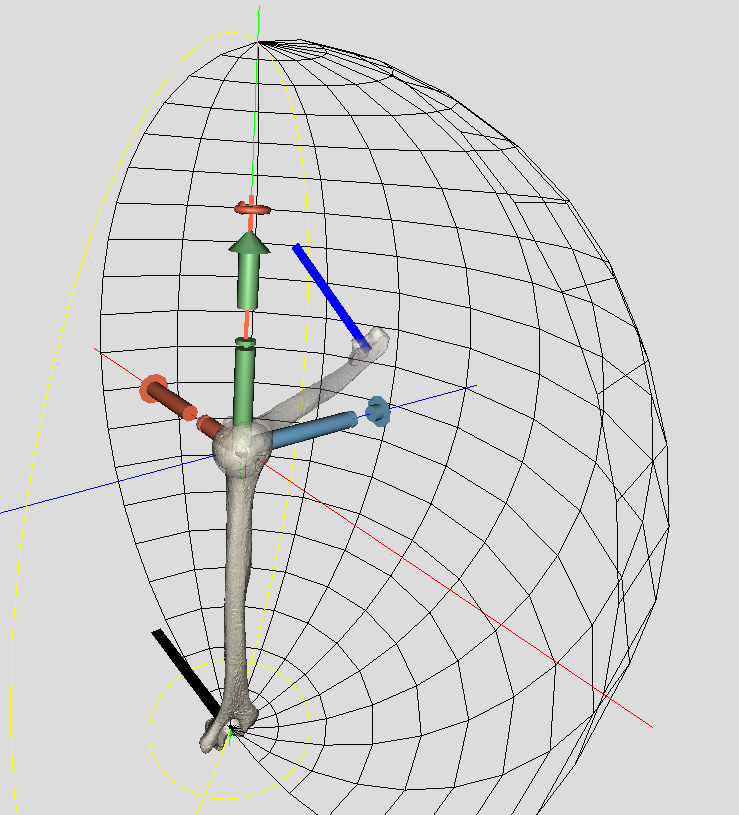

**Fig. A2a:** The yx'y'' decomposition sequence recommended by ISB is equivalent to a globe where the latitudes indicate elevation angle and longitudes indicate plane of elevation.

**REFERENCES**

[1] G. Wu, F.C. van der Helm, H.E. Veeger, M. Makhsous, P. Van Roy, C. Anglin, et al., ISB recommendation on definitions of joint coordinate systems of various joints for the reporting of human joint motion--Part II: shoulder, elbow, wrist and hand, Journal of biomechanics 38(5) (2005) 981-992.

[2] R. Baker, Globographic visualisation of three dimensional joint angles, Journal of biomechanics 44(10) (2011) 1885-91.

[3] P.M. Ludewig, V. Phadke, J.P. Braman, D.R. Hassett, C.J. Cieminski, R.F. LaPrade, Motion of the shoulder complex during multiplanar humeral elevation, The Journal of bone and joint surgery. American volume 91(2) (2009) 378-89.

[4] K. Matsuki, K.O. Matsuki, S. Yamaguchi, N. Ochiai, T. Sasho, H. Sugaya, et al., Dynamic in vivo glenohumeral kinematics during scapular plane abduction in healthy shoulders, The Journal of orthopaedic and sports physical therapy 42(2) (2012) 96-104.

[5] C.G.M. Meskers, H.M. Vermeulen, J.H. de Groot, F.C.T. van der Helm, P.M. Rozing, 3D shoulder position measurements using a six-degree-of-freedom electromagnetic tracking device, Clinical Biomechanics 13(4) (1998) 280-292. [http://www.sciencedirect.com/science/article/pii/S0268003398000953](http://www.sciencedirect.com/science/article/pii/S0268003398000953).

[6] M. Stokdijk, P.H.C. Eilers, J. Nagels, P.M. Rozing, External rotation in the glenohumeral joint during elevation of the arm, Clinical Biomechanics 18(4) (2003) 296-302. [http://www.sciencedirect.com/science/article/pii/S0268003303000172](http://www.sciencedirect.com/science/article/pii/S0268003303000172).

[7] J. Diebel, Representing Attitude : Euler Angles , Unit Quaternions , and Rotation Vectors, Stanford University, 2006.

[8] F. Hamano, Derivative of rotation matrix direct matrix derivation of well known formula, arXiv preprint arXiv:1311.6010  (2013).

[9] C.A. Doorenbosch, J. Harlaar, D.H. Veeger, The globe system: an unambiguous description of shoulder positions in daily life movements, Journal of rehabilitation research and development 40(2) (2003) 147-55.

[10] G.T. Rab, Shoulder motion description: The ISB and Globe methods are identical, Gait & posture 27(4) (2008) 702-705. [http://www.sciencedirect.com/science/article/pii/S0966636207001762.](http://www.sciencedirect.com/science/article/pii/S0966636207001762.)

function eulerAngles=euler_yxy_instrinsic(rotm)
    eulerAngles=zeros(1,3);
    if rotm(2,2)<1
        if rotm(2,2) > -1
            eulerAngles(2)=-acos(rotm(2,2));
            eulerAngles(1)=atan2(-rotm(1,2),-rotm(3,2));
            eulerAngles(3)=atan2(-rotm(2,1),rotm(2,3));
        else %rotm(2,2)=-1
            eulerAngles(1)=0;
            eulerAngles(2)=-pi;
            eulerAngles(3)=atan2(rotm(1,3),rotm(1,1));
        end
    else %rotm(2,2)=+1
        eulerAngles(1)=0;
        eulerAngles(2)=0;
        eulerAngles(3)=atan2(rotm(1,3),rotm(1,1));
    end
end